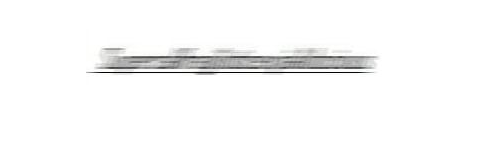

I = im2double(imread('mysteryWord.jpg'));
imshow(I)

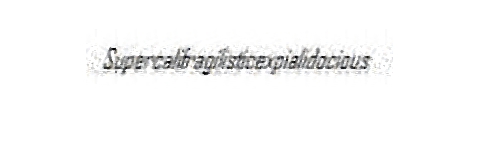


LEN = 20;
THETA = 1;
PSF = fspecial('motion',LEN,THETA);

noise_var = 0.00001;
signal_var = var(I(:));

J = deconvwnr(I,PSF,noise_var/signal_var);
J = medfilt3(J);
imshow(J)